Ejercicio 8 TP PID

Determine the controllers Gc1(s) and Gc2(s) such that, for the step disturbance input, the response shows a small amplitude and approaches zero quickly (in a matter of 1 to 2 sec). For the response to the unit-step reference input, it is desired that the maximum overshoot be 20% or less and the settling time 1 sec or less. For the ramp reference input and acceleration reference input, the steady-state errors should be zero.

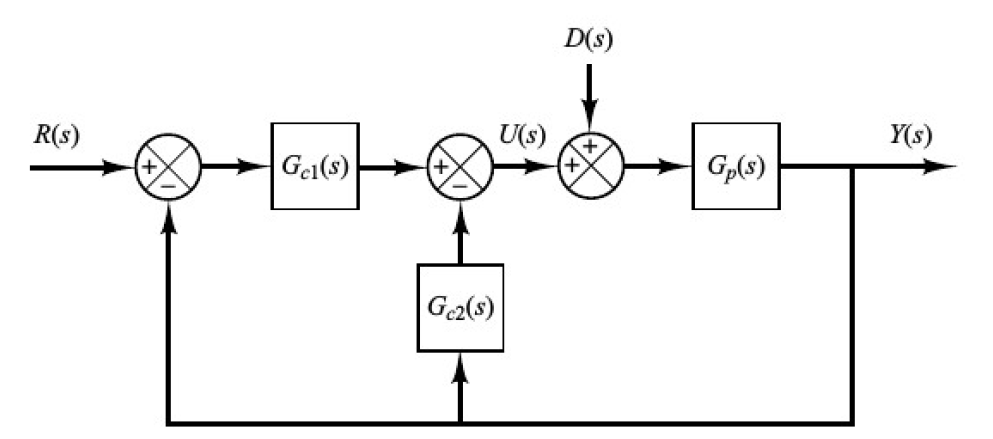

Restricciones:

syms Mp Ts dseta omega
eq1 = Mp == exp(-pi*dseta/sqrt(1-dseta^2));
eq2 = Ts == 4/(dseta*omega);

dseta = solve(eq1, dseta, 'Real', true)

$$dseta = \left(\begin{array}{c} \frac{\sqrt{{\log\left(\mathrm{Mp}\right)}^{2}\,\left({\log\left(\mathrm{Mp}\right)}^{2}+\pi^{2}\right)}}{{\log\left(\mathrm{Mp}\right)}^{2}+\pi^{2}}\\ -\frac{\sqrt{{\log\left(\mathrm{Mp}\right)}^{2}\,\left({\log\left(\mathrm{Mp}\right)}^{2}+\pi^{2}\right)}}{{\log\left(\mathrm{Mp}\right)}^{2}+\pi^{2}} \end{array}\right)$$

omega = solve(eq2, omega, 'Real', true)

$$omega = \frac{4}{\mathrm{Ts}\,\mathrm{dseta}}$$

Mp = 20% max

Ts = 1 s

Tr < 2 s

Mp = 20;
Ts = 1;
dseta = sqrt(log(Mp)^2*(log(Mp)^2+pi^2))/(log(Mp)^2+pi^2)

dseta = 0.6901

omega = 4/Ts*dseta

omega = 2.7604

Consideramos:


$$G_{\mathrm{c1}} \left(s\right)+G_{\mathrm{c2}} \left(s\right)=G_c \left(s\right)$$



$$\frac{Y\left(s\right)}{R\left(s\right)}=\frac{G_{\mathrm{c1}} G_P }{1+G_c G_P }$$



$$\frac{Y\left(s\right)}{D\left(s\right)}=\frac{G_P }{1+G_c G_P }$$


Suponemos un controlador PID de la forma:


$$G_c \left(s\right)=K_p \left(1+\frac{1}{T_i s}+T_d s\right)$$



$$\mathrm{Ti}\,z^4 +2\,\mathrm{Kp}\,\mathrm{Td}\,\mathrm{Ti}\,z^3 +8\,\mathrm{Ti}\,z^3 +2\,\mathrm{Kp}\,\mathrm{Td}\,\mathrm{Ti}\,z^2 +2\,\mathrm{Kp}\,\mathrm{Ti}\,z^2 +15\,\mathrm{Ti}\,z^2 +2\,\mathrm{Kp}\,\mathrm{Ti}\,z+2\,\mathrm{Kp}\,z+2\,\mathrm{Kp}$$


syms Kp Ti Td s Gc Gp D
Gp = 2*(s+1)/(s*(s+3)*(s+5))

$$Gp = \frac{2\,s+2}{s\,\left(s+3\right)\,\left(s+5\right)}$$

Gc = Kp*(1 + 1/(Ti*s) + Td*s)

$$Gc = \frac{K\,\left(a+s\right)\,\left(b+s\right)}{s}$$

D = 1+Gc*Gp

$$D = \frac{K\,\left(2\,s+2\right)\,\left(a+s\right)\,\left(b+s\right)}{s^{2}\,\left(s+3\right)\,\left(s+5\right)}+1$$

% Compute analytic solution of a symbolic equation
sol = solve(D,s);
% Display symbolic solution returned by solve
displaySymSolution(solution2);

Polinomio caracteristico del sistema:


$$\mathrm{Ti}\,z^4 +2\,\mathrm{Kp}\,\mathrm{Td}\,\mathrm{Ti}\,z^3 +8\,\mathrm{Ti}\,z^3 +2\,\mathrm{Kp}\,\mathrm{Td}\,\mathrm{Ti}\,z^2 +2\,\mathrm{Kp}\,\mathrm{Ti}\,z^2 +15\,\mathrm{Ti}\,z^2 +2\,\mathrm{Kp}\,\mathrm{Ti}\,z+2\,\mathrm{Kp}\,z+2\,\mathrm{Kp}=0$$


G_y = tf([])